# **Actividad: Ejercicios del Método de Runge Kutta de 4to orden**

Diego Alejandro Espejo López A01638341

Pablo Heredia Sahagún A01637103

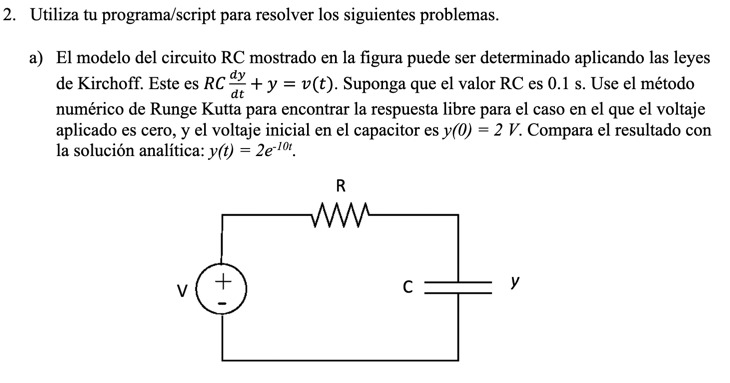

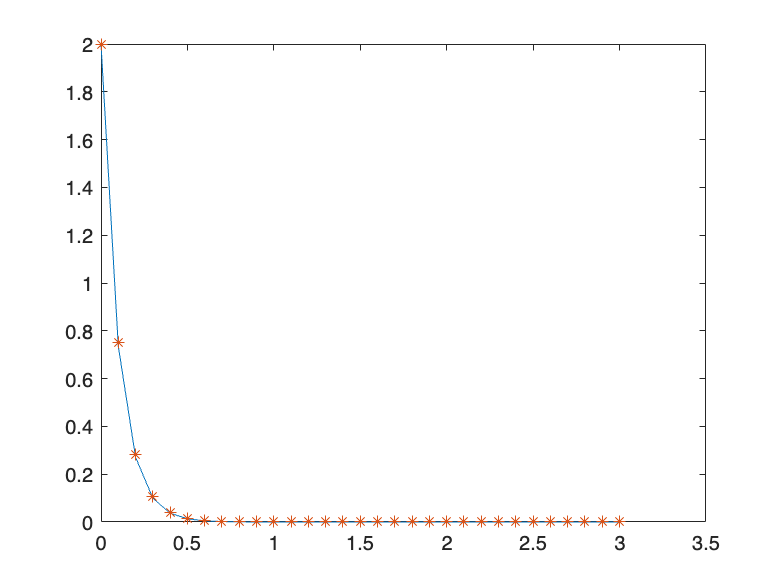

clear; clc;

xi = 0;
yi = 2;
xf = 3;
h = .1;
f = "-y / 0.1";

[x,y] = runge_kutta_4(h,xi,yi,xf,f);

xa = 0:0.1:3;
ya = 2.*exp(-10.*xa);
plot(xa,ya,x,y,"*")

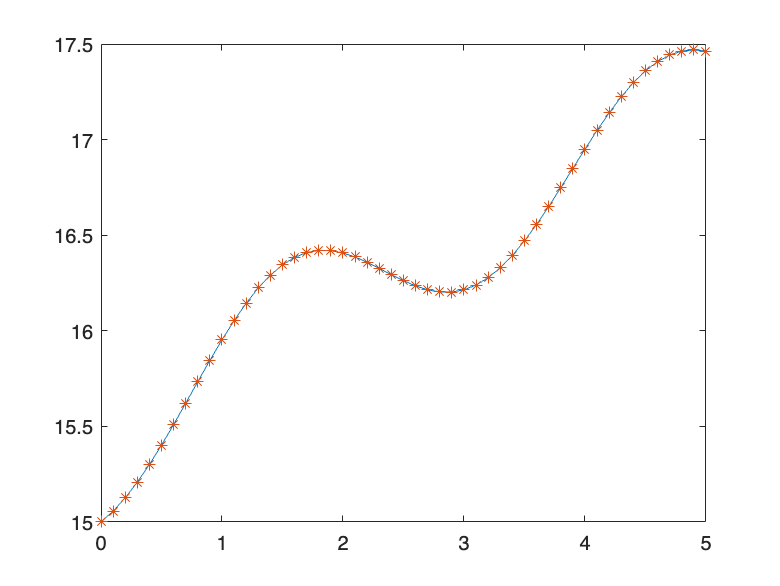

clear;clc;

xi = 0;
yi = 15;
xf = 5;
h = 0.1;
f = "(20 + 7*sin(2*x) - y)/10";

[x,y] = runge_kutta_4(h,xi,yi,xf,f);
xa = 0:0.1:5;
[xa,ya] = ode45(@(xa,ya) (20 + 7*sin(2*xa) - ya)/10, xa, yi);
plot(xa,ya,x,y,"*")

Examen 

xi = 0;
yi = 15;
xf = 5;
h = 0.1;
f = "(-5*sin(3*x) + y)/9";




[x,y] = runge_kutta_4(h,xi,yi,xf,f);

ans =    15.0000
   15.1593
   15.3045
   15.4375
   15.5618
   15.6813
   15.8011
   15.9259
   16.0605
   16.2089


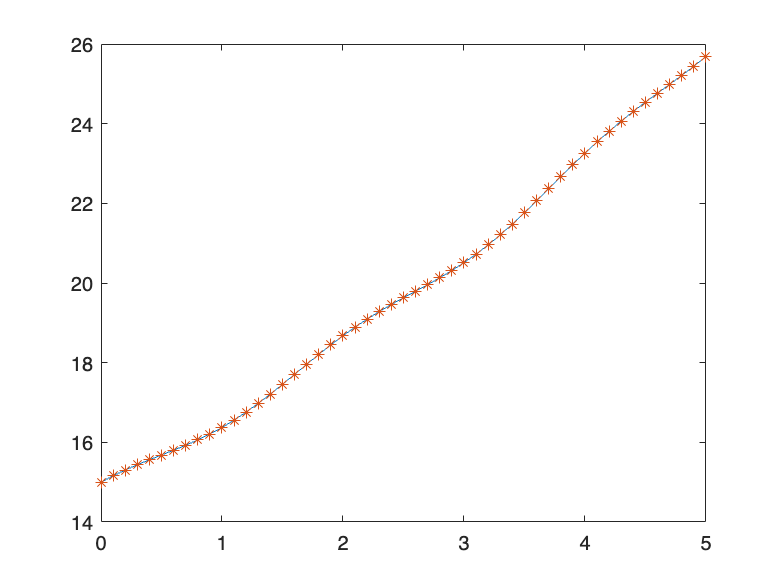



% Usando la función en matlab
xa = 0:0.1:5;
[xa,ya] = ode45(@(xa,ya) (-5*sin(3*xa) + ya)/9, xa, yi);
plot(xa,ya,x,y,"*")

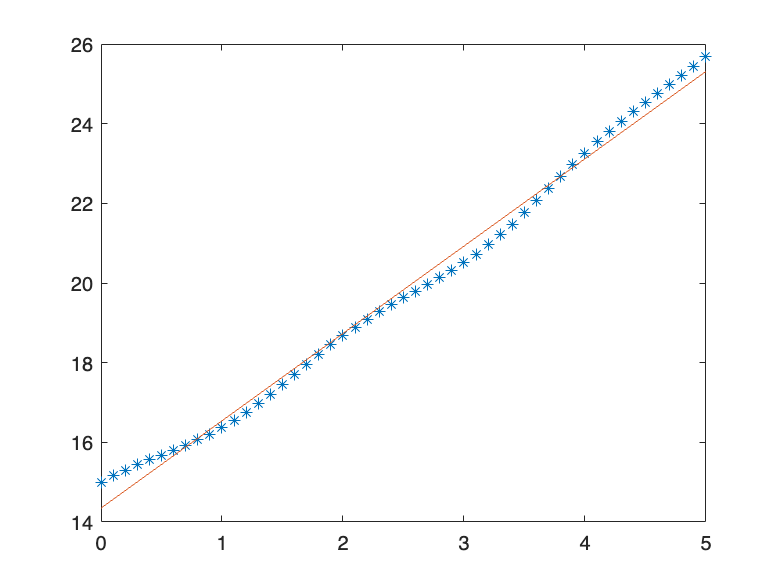


[a,b,r2] = min_cuad(x,y);

fprintf("y = %fx + %f", a, b);

y = 2.192670x + 14.348773

fprintf("R^2: %f", r2);

R^2: 0.992265

function [x,y] = runge_kutta_4(h,xi,yi,xf,f)
    f = str2func(strcat("@(x,y)", f));
    n = (xf - xi) / h;
    
    x = zeros(1, n+1);
    y = zeros(1, n+1);
    
    x(1) = xi;
    y(1) = yi;
    
    for i = 1:n
        x(i+1) = x(i) + h ;    
        k1 = f(x(i),y(i));
        k2 = f(x(i) + h/2, y(i) + (h/2)*k1);
        k3 = f(x(i) + h/2, y(i) + k2*(h/2));
        k4 = f(x(i) + h, y(i) + h*k3);
        y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end

function [a,b,r2] = min_cuad(x,y)
    n = numel(x);
    
    a = ((n*sum(x.*y)) - (sum(x)*sum(y))) / ((n*sum(x.^2) - sum(x)^2));
    b = (sum(y) - a*sum(x)) / (n);
    
    xP = sum(x) / numel(x);
    yP = sum(y) / numel(y);
    
    r = (sum((x-xP).*(y-yP))) / (sqrt(sum((x-xP).^2)) * sqrt(sum((y-yP).^2)));
    r2 = r^2;
    
    yy = a.*x + b;
    plot(x,y,'*',x,yy);
end

function [a,b] = min_cuad_4(x,y)
    n = numel(x);
    
    a = ((n*sum(x.*y)) - (sum(x)*sum(y))) / ((n*sum(x.^2) - sum(x)^2));
    b = (sum(y) - a*sum(x)) / (n);
    
    yy = a.*x + b;
    plot(x,y,'*',x,yy);
end